## **Author: MatNoble_HUST **

## **Date: 2019_6_10**

**Poisson Equation (2D)**


$$-\nabla \cdot(c \nabla u)=f$$


multiply v(x) and integral


$$-\int_{\Omega} \nabla \cdot(c \nabla u) v d x d y=\int_{\Omega} f v d x d y$$


Green's formula


$$\int_{\Omega} \nabla \cdot(c \nabla u) v d x d y=\int_{\partial \Omega}(c \nabla u \cdot \vec{n}) v d s-\int_{\Omega} c \nabla u \cdot \nabla v d x d y$$


then 


$$\int_{\Omega} c \nabla u \cdot \nabla v d x d y-\int_{\partial \Omega}(c \nabla u \cdot \vec{n}) v d s=\int_{\Omega} f v d x d y$$


and $v=0$ on $\partial \Omega$. then


$$\int_{\Omega} c \nabla u \cdot \nabla v d x d y=\int_{\Omega} f_{v} d x d y$$


i. e. **weak formulation**

find $u \in H^{1}(\Omega)$ such that


$$a(u, v)=(f, v)$$
 

for any $v \in H_{0}^{1}(\Omega)
$.

further, **Galerkin formulation**

find $u_{h} \in U_{h}$ such that


$$a\left(u_{h}, v_{h}\right)=\left(f, v_{h}\right)$$



$$\Leftrightarrow \int_{\Omega} c \nabla u_{h} \cdot \nabla v_{h} d x d y=\int_{\Omega} f v_{h} d x d y$$


for any $v_{h} \in U_{h}^{0}$.

Error_Max_norm: 1.78204e-05
Error_L2_norm: 7.72071e-06

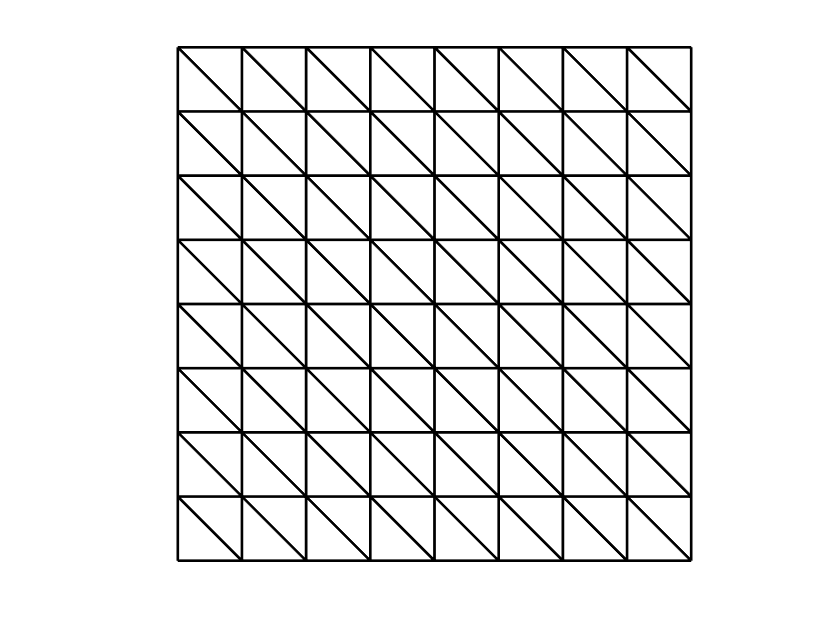

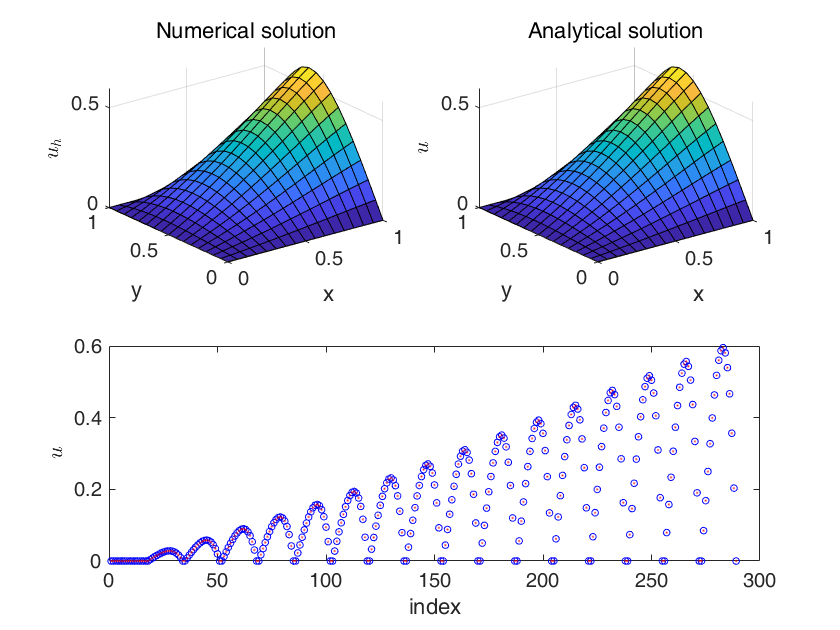

% [solution1, error_max1] = Poisson_2D(left, right, top, bottom,...
%                                      u, u_x, c, f, nx, ny,...
%                                      p, basis_type, Boundary_type)
% number of mesh elements
% p : Degree of distortion
% basis_type : 
              % 201 : 2D linear
              % 202 : 2D quadratic

%%%%%% 
u = @(x, y)(x.*y.*(1-x/2).*(1-y).*exp(x+y));
% u = @(x, y)(sin(x.*(x-1)).*sin(y.*(y-1)));
% u = @(x, y)((x+y)*0);

u_xy = @(x)(-exp(x-1));

c = @(x, y)((x+y)*0 + 1);

f = @(x, y)(-y*(1-y)*(1-x-(x^2)/2)*exp(x+y) - x*(1-x/2)*(-3*y-y^2)*exp(x+y));
% f = @(x, y)(sin(x*(x - 1))*sin(y*(y - 1))*(2*x - 1)^2 - 2*cos(y*(y - 1))*sin(x*(x - 1)) - 2*cos(x*(x - 1))*sin(y*(y - 1)) + sin(x*(x - 1))*sin(y*(y - 1))*(2*y - 1)^2);
% f = @(x, y)((x+y)*0 + 1);
%%%%%% 

%%%%%% Example 1
left = 0;  right = 1;
bottom = 0;  top = 1;
nx = 8;    ny = 8;
p = 0; 
basis_type = 202; % 2D linear
Boundary_type = [1, 1, 1, 1]; % Neumann
[solution1] = Poisson_2D(left, right, top, bottom,...
                                     u, u_xy, c, f, nx, ny,...
                                     p, basis_type, Boundary_type);


% %%%%%% Example 2
% left = -1;  right = 1;
% bottom = -1;  top = 1;
% nx = 4;    ny = 5;
% p = 0; 
% basis_type = 202; % 2D linear
% Boundary_type = [1, 1, 1, 1]; % Neumann
% [solution2, error_max2] = Poisson_2D(left, right, top, bottom,...
%                                      u, u_xy, c, f, nx, ny,...
%                                      p, basis_type, Boundary_type)